## Modelo

### Variaveis simbólicas

clear;
syms r l m_w m_b G_r I_w I_b V_max s_t w_m g k 
syms a b c d e j
syms theta(t) phi(t) T_w V 
syms s

## Equações do movimento

% x(t) = phi(t) * r
% substituí para ficar mais parecido com o pdf

% eq1 = (I_b + m_b*l^2)*diff(theta,2) == m_b*g*l*sin(theta) - m_b*l*cos(theta)*r*diff(phi,2) - T_w
% eq2 = ((m_b + 2*m_w)*r^2 + 2*I_w)*diff(phi,2) == -m_b*r*l*cos(theta)*diff(theta,2) + m_b*r*l*diff(theta)^2*sin(theta) + T_w


$$omega_m = (\dot{\phi} - \dot{\theta}) \, G_r; \\
T_w = 2 \, G_r \, (s_t \, V - k \, \omega_m); \\
T_w = 2 \, G_r s_t \frac{V}{V_{max}} - 2 \, G_r \, ^2  \, k \, \dot{\phi} + 2 \, G_r \, ^2 \, k \, \dot{\theta}.$$


eq1 = d*sin(theta) + j*diff(phi) == e*V + j*diff(theta) + c*diff(theta,2) + b*cos(theta)*diff(phi,2)

$$eq1(t) = j\,\frac{\partial }{\partial t}\varphi \left(t\right)+d\,\sin\left(\theta \left(t\right)\right)=V\,e+j\,\frac{\partial }{\partial t}\theta \left(t\right)+c\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)+b\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\varphi \left(t\right)$$

eq2 = j*diff(phi) + b*cos(theta)*diff(theta,2) + a*diff(phi,2) == e*V + j*diff(theta) + b*sin(theta)*diff(theta)^2

$$eq2(t) = j\,\frac{\partial }{\partial t}\varphi \left(t\right)+a\,\frac{\partial^{2}}{\partial t^{2}}\varphi \left(t\right)+b\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)=b\,\sin\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}+j\,\frac{\partial }{\partial t}\theta \left(t\right)+V\,e$$

### Com as variaveis reais

VarAux = [a, b, c, d, e, j];
VarReal = [2*I_w + (m_b + 2*m_w) * r^2, m_b*r*l, I_b + m_b*l^2, m_b*g*l, 2*G_r*s_t/V_max, 2*G_r^2*k];
subs(eq1,VarAux, VarReal)

$$ans(t) = 2\,k\,{G_{r}}^{2}\,\frac{\partial }{\partial t}\varphi \left(t\right)+g\,l\,m_{b}\,\sin\left(\theta \left(t\right)\right)=\left(m_{b}\,l^{2}+I_{b}\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)+2\,{G_{r}}^{2}\,k\,\frac{\partial }{\partial t}\theta \left(t\right)+\frac{2\,G_{r}\,V\,s_{t}}{V_{\max}}+l\,m_{b}\,r\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\varphi \left(t\right)$$

subs(eq2,VarAux, VarReal)

$$ans(t) = \left(\left(m_{b}+2\,m_{w}\right)\,r^{2}+2\,I_{w}\right)\,\frac{\partial^{2}}{\partial t^{2}}\varphi \left(t\right)+2\,{G_{r}}^{2}\,k\,\frac{\partial }{\partial t}\varphi \left(t\right)+l\,m_{b}\,r\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)=2\,{G_{r}}^{2}\,k\,\frac{\partial }{\partial t}\theta \left(t\right)+\frac{2\,G_{r}\,V\,s_{t}}{V_{\max}}+l\,m_{b}\,r\,\sin\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}$$

## Manipulação algébrica

ddphi = rhs(isolate(eq2,diff(phi,2)));
ddtheta = rhs(isolate(eq1,diff(theta,2)));
eq_ddtheta = isolate(subs(isolate(eq1, diff(theta,2)), diff(phi,2), ddphi), diff(theta,2))

$$eq\_ddtheta = \begin{array}{l} \frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)=\frac{V\,e-d\,\sin\left(\theta \left(t\right)\right)-\sigma_{2}+\sigma_{1}+\frac{b\,\cos\left(\theta \left(t\right)\right)\,\left(V\,e-\sigma_{2}+\sigma_{1}+b\,\sin\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}\right)}{a}}{c\,\left(\frac{b^{2}\,{\cos\left(\theta \left(t\right)\right)}^{2}}{a\,c}-1\right)}\\ \mathrm{where}\\ \sigma_{1}=j\,\frac{\partial }{\partial t}\theta \left(t\right)\\ \sigma_{2}=j\,\frac{\partial }{\partial t}\varphi \left(t\right) \end{array}$$

eq_ddphi = isolate(subs(isolate(eq2,diff(phi,2)), diff(theta,2), ddtheta), diff(phi,2))

$$eq\_ddphi = \begin{array}{l} \frac{\partial^{2}}{\partial t^{2}}\varphi \left(t\right)=-\frac{V\,e-\sigma_{2}+\sigma_{1}+b\,\sin\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}+\frac{b\,\cos\left(\theta \left(t\right)\right)\,\left(V\,e-d\,\sin\left(\theta \left(t\right)\right)-\sigma_{2}+\sigma_{1}\right)}{c}}{a\,\left(\frac{b^{2}\,{\cos\left(\theta \left(t\right)\right)}^{2}}{a\,c}-1\right)}\\ \mathrm{where}\\ \sigma_{1}=j\,\frac{\partial }{\partial t}\theta \left(t\right)\\ \sigma_{2}=j\,\frac{\partial }{\partial t}\varphi \left(t\right) \end{array}$$

## Espaço de estados

- Estados: dtheta, dx, theta, x.

### Matriz A

A1 = (rhs(eq_ddtheta))

$$A1 = \begin{array}{l} \frac{V\,e-d\,\sin\left(\theta \left(t\right)\right)-\sigma_{2}+\sigma_{1}+\frac{b\,\cos\left(\theta \left(t\right)\right)\,\left(V\,e-\sigma_{2}+\sigma_{1}+b\,\sin\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}\right)}{a}}{c\,\left(\frac{b^{2}\,{\cos\left(\theta \left(t\right)\right)}^{2}}{a\,c}-1\right)}\\ \mathrm{where}\\ \sigma_{1}=j\,\frac{\partial }{\partial t}\theta \left(t\right)\\ \sigma_{2}=j\,\frac{\partial }{\partial t}\varphi \left(t\right) \end{array}$$

A2 = rhs(eq_ddphi)

$$A2 = \begin{array}{l} -\frac{V\,e-\sigma_{2}+\sigma_{1}+b\,\sin\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}+\frac{b\,\cos\left(\theta \left(t\right)\right)\,\left(V\,e-d\,\sin\left(\theta \left(t\right)\right)-\sigma_{2}+\sigma_{1}\right)}{c}}{a\,\left(\frac{b^{2}\,{\cos\left(\theta \left(t\right)\right)}^{2}}{a\,c}-1\right)}\\ \mathrm{where}\\ \sigma_{1}=j\,\frac{\partial }{\partial t}\theta \left(t\right)\\ \sigma_{2}=j\,\frac{\partial }{\partial t}\varphi \left(t\right) \end{array}$$

A3 = diff(theta);
A4 = diff(phi);

## Linearização

syms dtheta_ dphi_ theta_ phi_
q = [dtheta_; dphi_; theta_; phi_];
dtheta_ = diff(theta);
dphi_ = diff(phi);
theta_ = theta;
phi_ = phi;
q = subs(q);

clear dtheta_ dphi_ theta_ phi_
theta(t) = 0;
phi(t) = 0;

A11 = (subs(diff(A1, q(1))));
A12 = (subs(diff(A1, q(2))));
A13 = (subs(diff(A1, q(3))));
A14 = (subs(diff(A1, q(4))));
A21 = (subs(diff(A2, q(1))));
A22 = (subs(diff(A2, q(2))));
A23 = (subs(diff(A2, q(3))));
A24 = (subs(diff(A2, q(4))));
A31 = (subs(diff(A3, q(1))));
A32 = (subs(diff(A3, q(2))));
A33 = (subs(diff(A3, q(3))));
A34 = (subs(diff(A3, q(4))));
A41 = (subs(diff(A4, q(1))));
A42 = (subs(diff(A4, q(2))));
A43 = (subs(diff(A4, q(3))));
A44 = (subs(diff(A4, q(4))));
A = [A11 A12 A13 A14; A21 A22 A23 A24; A31 A32 A33 A34; A41 A42 A43 A44]

$$A(t) = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{2} & -\sigma_{2} & -\frac{d}{c\,\sigma_{3}} & 0\\ -\sigma_{1} & \sigma_{1} & \frac{b\,d}{a\,c\,\sigma_{3}} & 0\\ 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{j+\frac{b\,j}{c}}{a\,\sigma_{3}}\\ \sigma_{2}=\frac{j+\frac{b\,j}{a}}{c\,\sigma_{3}}\\ \sigma_{3}=\frac{b^{2}}{a\,c}-1 \end{array}$$

B11 = subs(diff(A1, V));
B21 = subs(diff(A2, V));
B31 = subs(diff(A3, V));
B41 = subs(diff(A4, V));
B = [B11; B21; B31; B41]

$$B(t) = \left(\begin{array}{c} \frac{e+\frac{b\,e}{a}}{c\,\left(\frac{b^{2}}{a\,c}-1\right)}\\ -\frac{e+\frac{b\,e}{c}}{a\,\left(\frac{b^{2}}{a\,c}-1\right)}\\ 0\\ 0 \end{array}\right)$$

### Modelo linearizado reduzido

A = simplify([A11 A12 A13; A21 A22 A23; A31 A32 A33])

$$A(t) = \begin{array}{l} \left(\begin{array}{ccc} -\frac{j\,\left(a+b\right)}{\sigma_{1}} & \frac{j\,\left(a+b\right)}{\sigma_{1}} & \frac{a\,d}{\sigma_{1}}\\ \frac{j\,\left(b+c\right)}{\sigma_{1}} & -\frac{j\,\left(b+c\right)}{\sigma_{1}} & -\frac{b\,d}{\sigma_{1}}\\ 1 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=a\,c-b^{2} \end{array}$$

B = simplify([B11; B21; B31])

$$B(t) = \left(\begin{array}{c} -\frac{e\,\left(a+b\right)}{a\,c-b^{2}}\\ \frac{e\,\left(b+c\right)}{a\,c-b^{2}}\\ 0 \end{array}\right)$$

C = [0 0 1; 0 1 0]

C =      0     0     1
     0     1     0


% q = [q(1); q(2); q(3)]

## Substituição dos valores

### Obtendo as Variavveis que faltam

#### Funções de transferencia simbólicas

Experimento do corpo

-e/c*s / (s^2 + j/c*s + d/c)

$$ans = -\frac{e\,s}{c\,\left(\frac{d}{c}+s^{2}+\frac{j\,s}{c}\right)}$$

Experiemento das rodas

e/a / (s + j/a)

$$ans = \frac{e}{a\,\left(s+\frac{j}{a}\right)}$$

#### Equações obtidas dos experimentos

Experimento do corpo

load tf_corpo.mat;
K_corpo

K_corpo = -0.0392

zeta

zeta = 0.0505

omega

omega = 9.0013

tf([K_corpo 0], [1 2*zeta*omega omega^2])

ans =
 
        -0.03921 s
  ----------------------
  s^2 + 0.9096 s + 81.02
 
Continuous-time transfer function.
Model Properties


Experimento das rodas

load tf_rodas.mat
K_rodas = -K_rodas

K_rodas = 8.9048

tau

tau = 0.0556

tf([K_rodas], [tau 1])

ans =
 
      8.905
  -------------
  0.05556 s + 1
 
Continuous-time transfer function.
Model Properties


#### Relações

Variáveis auxiliares 

a = 2*I_w + (m_b + 2*m_w) * r^2;
b = m_b*r*l;
c = I_b + m_b*l^2;
d = m_b*g*l;
e = 2*G_r*s_t/V_max;
j = 2*G_r^2*k;

Experimento do corpo

eq1 = K_corpo*omega^2 == -e/c

$$eq1 = -\frac{3577176866161867}{1125899906842624}=-\frac{2\,G_{r}\,s_{t}}{V_{\max}\,\left(m_{b}\,l^{2}+I_{b}\right)}$$

eq2 = 2*zeta*omega == j/c

$$eq2 = \frac{2048155021496123}{2251799813685248}=\frac{2\,{G_{r}}^{2}\,k}{m_{b}\,l^{2}+I_{b}}$$

eq3 = omega^2 == d/c

$$eq3 = \frac{5701556550091139}{70368744177664}=\frac{g\,l\,m_{b}}{m_{b}\,l^{2}+I_{b}}$$

Experimento das rodas

a = 2*I_w;
eq4 = K_rodas == e/a

$$eq4 = \frac{5012936912199491}{562949953421312}=\frac{G_{r}\,s_{t}}{I_{w}\,V_{\max}}$$

eq5 = 1/tau == j/a

$$eq5 = 18=\frac{{G_{r}}^{2}\,k}{I_{w}}$$

#### Valores das variáveis

r = 3 / 100;
l = 8 / 100;
m_w = 12 / 1000;
m_b = 216 / 1000;
G_r = 30;
V_max = 7.4;
g = 9.81;

#### Substituições

I_b = double(vpa(rhs(isolate(subs(eq3), I_b)), 4))

I_b = 7.0978e-04

s_t = double(vpa(rhs(isolate(subs(eq1), s_t)), 4))

s_t = 8.1982e-04

k = double(vpa(rhs(isolate(subs(eq2), k)),4))

k = 1.0572e-06

I_w = double(rhs(isolate(subs(eq4), I_w)))

I_w = 3.7324e-04

% double(vpa(rhs(isolate(subs(eq5), I_w)),4))

a = 2*I_w + (m_b + 2*m_w) * r^2;
[double(subs(a)) double(subs(b)) double(subs(c)) double(subs(d)) double(subs(e)) double(subs(j))]

ans =     0.0010    0.0005    0.0021    0.1695    0.0066    0.0019


### Matrizes numéricas


% G_r = 35.555;
% k = 1.7045 * 10^-6;
% s_t = 0.003;
% l = 4.77 / 100;
% r = 3.4 / 100;
% g = 9.81;
% m_b = 180 / 1000;
% m_w = 27 / 1000;
% I_b = 2.63*10^-4;
% I_w = 1.22 * 10^-4;
% V_max = 7.4;




An = double(subs(subs(A)))

An =    -1.6150    1.6150   93.5025
    2.8470   -2.8470  -50.3613
    1.0000         0         0


Bn = double(subs(subs(B)))

Bn =    -5.6413
    9.9448
         0


clear q phi theta V T_w VarAux VarReal s t
clear K_rodas tau K_corpo omega zeta
clear a b c d e j
clear eq1 eq2 eq3 eq4 eq5
clear eq_ddphi eq_ddtheta
clear ddphi ddtheta
clear A1 A2 A3 A4
clear A11 A12 A13 A14 A21 A22 A23 A24 A31 A32 A33 A34 A41 A42 A43 A44
clear B11 B21 B31 B41
% clear r l m_w m_b G_r I_w I_b V_max s_t w_m g k 

## Funções de transferência


$$sX(s) = AX(s) + BU(s) \\
(Is - A)X(s) = BU(s) \\ \\

Y(s) = CX(s) + DU(s) \\
G(s) = \frac{Y(s)}{U(s)} = C(Is-A)^{-1}B + D$$


% eye(3)*s - A
% inv(eye(3)*s - A)
% C * inv(eye(3)*s - A)
% C * inv(eye(3)*s - A) * B
% G = vpa(simplify(C * inv(eye(3)*s - A) * B),4)

zpk(ss(An,Bn,C,0))

ans =
 
  From input to output...
                -5.6413 s
   1:  ---------------------------
       (s-8.71) (s+11.29) (s+1.88)
 
       9.9448 (s+8.058) (s-8.058)
   2:  ---------------------------
       (s-8.71) (s+11.29) (s+1.88)
 
Continuous-time zero/pole/gain model.
Model Properties


G1 = ans(1)

G1 =
 
           -5.6413 s
  ---------------------------
  (s-8.71) (s+11.29) (s+1.88)
 
Continuous-time zero/pole/gain model.
Model Properties


G2 = ans(2)

G2 =
 
  9.9448 (s+8.058) (s-8.058)
  ---------------------------
  (s-8.71) (s+11.29) (s+1.88)
 
Continuous-time zero/pole/gain model.
Model Properties


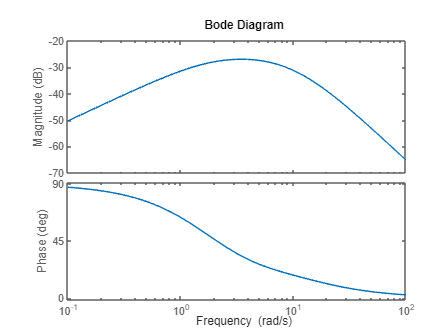

bode(G1)

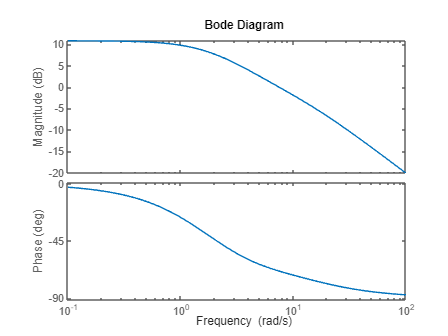

bode(G2)

#### Valores eduMIP

% clear
Vb = 7.4; % battery voltage [V]
st = 0.003; % stall torque of motor sans gearbox [N m]
Gr = 35.5555; % gearbox gear ratio [unitless]
Im = 3.6*10^-8; % motor armature moment of inertia [kg m^2]
rw = 0.034; % wheel radius [r]
mw = 0.027; % mass of each wheel [kg]
mb = 0.180; % mass of robot body [kg]
L = 0.0477; % length from center of mass to wheel axis [m]
Ib=0.000263; % Robot body moment of inertia [kg m^2]
g=9.81; % gravity [m/s^2]
wf = 1760; % motor no load angular velocity [rad/sec]
k=st/wf; % torque constant [N m/s]
Iw=2*((mw*rw^2)/2+Gr^2*Im); % wheel inertia [kg m^2]


#### Modelo eduMIP

%transfer functions to be used in G1
BA=tf([mb*rw*L -2*Gr^2*k 0],[Iw+(mb+mw)*rw^2 2*Gr^2*k 0]);
CA=tf([2*Gr*st],[Iw+(mb+mw)*rw^2 2*Gr^2*k 0]);
ED=tf([Ib+mb*L^2 2*Gr^2*k -mb*g*L],[mb*rw*L -2*Gr^2*k 0]);
FD=tf([-2*Gr*st],[mb*rw*L -2*Gr^2*k 0]);

#### Planta eduMIP segundo a modelagem eduMIP

G_eduMIP = (CA-FD)/(BA-ED)

G_eduMIP =
 
                         -1.471e-11 s^6 + 4.182e-11 s^5 + 2.589e-09 s^4
  ---------------------------------------------------------------------------------------------
  1.667e-14 s^8 + 6.885e-13 s^7 - 8.239e-12 s^6 - 1.587e-10 s^5 + 6.745e-10 s^4 + 6.742e-09 s^3
 
Continuous-time transfer function.
<a href="matlab:disp(char('','       Numerator: {[0 0 1.4712e-11 -4.1816e-11 -2.5893e-09 0 0 0 0]} ','     Denominator: {[-1.6667e-14 -6.8853e-13 8.2387e-12 1.5869e-10 -6.7448e-10 -6.7424e-09 0 0 0]} ','        Variable: ''s'' ','         IODelay: [0] ','      InputDelay: [0] ','     OutputDelay: [0] ','       InputName: {''''} ','       InputUnit: {''''} ','      InputGroup: [1×1 struct] ','      OutputName: {''''} ','      OutputUnit: {''''} ','     OutputGroup: [1×1 struct] ','           Notes: [0×1 string] ','        UserData: [] ','            Name: '''' ','              Ts: [0] ','        TimeUnit: ''seconds'' ','    SamplingGrid: [1×1 struct] ',' '))">Model Properties</a

G_eduMIP = zpk(minreal(G_eduMIP))

G_eduMIP =
 
           -882.71 s
  ----------------------------
  (s+47.21) (s-8.67) (s+5.616)
 
Continuous-time zero/pole/gain model.
Model Properties


#### Valores do pêndulo

Vb = 7.4;
st = s_t;
Gr = G_r;
r_w = r;
mw = m_w;
mb = m_b;
L = l;
Ib = I_b;
Iw = I_w;

%transfer functions to be used in G1
BA=tf([mb*rw*L -2*Gr^2*k 0],[Iw+(mb+mw)*rw^2 2*Gr^2*k 0]);
CA=tf([2*Gr*st],[Iw+(mb+mw)*rw^2 2*Gr^2*k 0]);
ED=tf([Ib+mb*L^2 2*Gr^2*k -mb*g*L],[mb*rw*L -2*Gr^2*k 0]);
FD=tf([-2*Gr*st],[mb*rw*L -2*Gr^2*k 0]);

#### Planta do pêndulo segundo a modelagem eduMIP

G_ = (CA-FD)/(BA-ED)

G_ =
 
                         -2.253e-11 s^6 + 9.107e-12 s^5 + 5.669e-10 s^4
  --------------------------------------------------------------------------------------------
  3.693e-13 s^8 + 4.332e-12 s^7 - 5.149e-11 s^6 - 2.91e-10 s^5 + 1.095e-09 s^4 + 4.896e-09 s^3
 
Continuous-time transfer function.
Model Properties


G_ = zpk(minreal(G_))

G_ =
 
            -61.009 s
  -----------------------------
  (s+16.78) (s-8.389) (s+3.743)
 
Continuous-time zero/pole/gain model.
Model Properties


#### Dados do artigo eduMIP

G_r = 35.555;
k = 1.7045 * 10^-6;
s_t = 0.003;
l = 4.77 / 100;
r = 3.4 / 100;
g = 9.81;
m_b = 180 / 1000;
m_w = 27 / 1000;
I_b = 2.63*10^-4;
I_w = 1.22 * 10^-4;
V_max = 7.4;

#### Variáveis auxiliares

a = 2*I_w + (m_b + 2*m_w) * r^2;
b = m_b*r*l;
c = I_b + m_b*l^2;
d = m_b*g*l;
e = 2*G_r*s_t/V_max;
j = 2*G_r^2*k;

#### Matrizes do eduMIP segundo a nossa modelagem

An = double(subs(subs(A)))

An =   -13.3250   13.3250  166.1585
   15.9365  -15.9365  -94.2765
    1.0000         0         0


Bn = double(subs(subs(B)))

Bn =   -89.1373
  106.6070
         0


zpk(ss(An,Bn,C,0))

ans =
 
  From input to output...
                 -89.137 s
   1:  -----------------------------
       (s+33.02) (s-8.636) (s+4.881)
 
        106.61 (s-9.345) (s+9.345)
   2:  -----------------------------
       (s+33.02) (s-8.636) (s+4.881)
 
Continuous-time zero/pole/gain model.
Model Properties


#### Planta eduMIP segundo nossa modelagem

G1_eduMIP = ans(1)

G1_eduMIP =
 
            -89.137 s
  -----------------------------
  (s+33.02) (s-8.636) (s+4.881)
 
Continuous-time zero/pole/gain model.
Model Properties


## Comparação das plantas

### Planta eduMIP segundo a nossa modelagem

G1_eduMIP

G1_eduMIP =
 
            -89.137 s
  -----------------------------
  (s+33.02) (s-8.636) (s+4.881)
 
Continuous-time zero/pole/gain model.
Model Properties


### Planta eduMIP segundo a modelagem eduMIP

G_eduMIP

G_eduMIP =
 
           -882.71 s
  ----------------------------
  (s+47.21) (s-8.67) (s+5.616)
 
Continuous-time zero/pole/gain model.
Model Properties


### Planta do pêndulo segundo a nossa modelagem

G1

G1 =
 
           -5.6413 s
  ---------------------------
  (s-8.71) (s+11.29) (s+1.88)
 
Continuous-time zero/pole/gain model.
Model Properties


### Planta do pêndulo segundo a modelagem eduMIP

G_

G_ =
 
            -61.009 s
  -----------------------------
  (s+16.78) (s-8.389) (s+3.743)
 
Continuous-time zero/pole/gain model.
Model Properties
